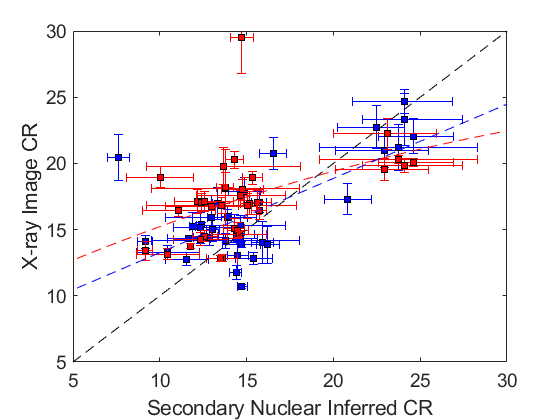

data = xlsread('SecondaryData.xlsx');

nucCR = data(:, 22:24);
nucCR = nucCR(~isnan(nucCR(:,1)), :);

tiCR = data(1:length(nucCR), 25:26);
trCR = data(1:length(nucCR), 27:28);

fTI = fit(nucCR(~isnan(tiCR(:,1)),1), tiCR(~isnan(tiCR(:,1)),1), 'poly2');
fTR = fit(nucCR(~isnan(trCR(:,1)),1), trCR(~isnan(trCR(:,1)),1), 'poly1');

figure; hold on; box on;
xlim([5 30])
ylim([5 30])

xlabel('Secondary Nuclear Inferred CR')
ylabel('X-ray Image CR')
set(gca, 'FontSize', 14)

errorbar(nucCR(:,1), trCR(:,1), trCR(:,2), trCR(:,2), nucCR(:,2), nucCR(:,3), ...
    'LineStyle', 'none', ...
    'Color', 'b', ...
    'Marker', 'square', ...
    'MarkerEdgeColor', 'k', ...
    'MarkerFaceColor', 'b')

errorbar(nucCR(:,1), tiCR(:,1), tiCR(:,2), tiCR(:,2), nucCR(:,2), nucCR(:,3), ...
    'LineStyle', 'none', ...
    'Color', 'r', ...
    'Marker', 'square', ...
    'MarkerEdgeColor', 'k', ...
    'MarkerFaceColor', 'r')




plot([0 100], [0 100], '--k')
plot(0:100, fTI(0:100), '--r')
plot(0:100, fTR(0:100), '--b')